clear
close all
clc

% Cylinder parameters
r = 2;        % [m]
h = 4;        % [m]
m_cyl = 1000; % [kg]

% Rod parameters
l = 1;        % [m]
m_rod = 5;    % [kg]

% Panel parameters
b = 2;                % [m]
a = 1;                % [m]
m_pan = 25;           % [kg]
theta = deg2rad(-10); % [rad]

% Use this for symbolic expression
% syms r h m_cyl l m_rod b a m_pan theta
% assume([r h m_cyl l m_rod b a m_pan theta], 'real')

% Mass centers relative to cylinder center
r_cyl_c_o = [0; 0; 0];
r_rod_c_o = [0; r + l / 2; 0];
r_pan_c_o = [0; r + l + a / 2; 0];

% Inertia about mass centers
I_cyl_c_c = m_cyl * diag([(3 * r^2 + h^2) / 12, ...
                          (3 * r^2 + h^2) / 12, ...
                          r^2 / 2]);

I_rod_c_c = m_rod * diag([l^2 / 12, 0, l^2 / 12]);

I_pan_c_p = m_pan * diag([(b^2 + a^2) / 12, ...
                          a^2 / 12, ...
                          b^2 / 12]);

% Rotate panel inertia
R_pc = rot_2(theta);
I_pan_c_c = R_pc' * I_pan_c_p * R_pc;

% Apply parallel axis theorem
I_cyl_o_c = I_cyl_c_c + m_cyl * skew(r_cyl_c_o)' * skew(r_cyl_c_o);
I_rod_o_c = I_rod_c_c + m_rod * skew(r_rod_c_o)' * skew(r_rod_c_o);
I_pan_o_c = I_pan_c_c + m_pan * skew(r_pan_c_o)' * skew(r_pan_c_o);

% Total inertia about cylinder center
I_comp_o_b = I_cyl_o_c + I_rod_o_c + I_pan_o_c;

% Center of mass
M = m_cyl + m_rod + m_pan;
r_c_o = (m_cyl * r_cyl_c_o + m_rod * r_rod_c_o + m_pan * r_pan_c_o) / M;

% Total inertia about center of mass
I_comp_c_b = I_comp_o_b - M * skew(r_c_o)' * skew(r_c_o);

% Diagonalize inertia matrix
[R_bc, I_b] = reorder_axes_and_mois(I_comp_c_b);

% Euler angle
[phi, ~] = rot_to_eul(R_bc);
phi = rad2deg(phi);

% Initial conditions
w_0 = [1; 0; 0];
R_0 = eye(3);
q_0 = rot_to_quat(R_0);
q_0 = q_0 / norm(q_0);

% Integration
t_span = [0 10];
[t, sol] = ode45(@(t, y) odefunc(t, y, I_b), t_span, [w_0; q_0]);

% Extract solution
w_history = sol(:, 1:3);
q_history = sol(:, 4:7);

% Plot results
fs = 14; % Set font size
lineWidth = 2; % Set line width for thicker plots

figure;

% Subplot for Angular Velocity
subplot(2, 1, 1);

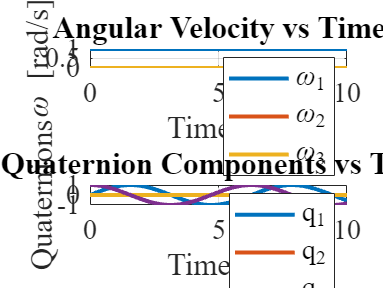

plot(t, w_history, 'LineWidth', lineWidth); % Set line width
grid on;
xlabel('Time [s]', 'FontName', 'Times New Roman', 'FontSize', fs);
ylabel('\omega [rad/s]', 'FontName', 'Times New Roman', 'FontSize', fs);
legend('\omega_1', '\omega_2', '\omega_3', 'FontName', 'Times New Roman', 'FontSize', fs);
title('Angular Velocity vs Time', 'FontName', 'Times New Roman', 'FontSize', fs);
set(gca, 'FontName', 'Times New Roman', 'FontSize', fs); % Set font for axes

% Subplot for Quaternion Components
subplot(2, 1, 2);
plot(t, q_history, 'LineWidth', lineWidth); % Set line width
grid on;
xlabel('Time [s]', 'FontName', 'Times New Roman', 'FontSize', fs);
ylabel('Quaternions', 'FontName', 'Times New Roman', 'FontSize', fs);
legend('q_1', 'q_2', 'q_3', 'q_4', 'FontName', 'Times New Roman', 'FontSize', fs);
title('Quaternion Components vs Time', 'FontName', 'Times New Roman', 'FontSize', fs);
set(gca, 'FontName', 'Times New Roman', 'FontSize', fs); % Set font for axes


% Function to define the differential equations for angular velocity and quaternion
function dydt = odefunc(t, y, I)
    w = y(1:3);  % Angular velocity [rad/s]
    q = y(4:7);  % Quaternion

    % Compute the angular acceleration (w_dot)
    w_dot = -I' * skew(w) * I * w;  % Assuming no external forces (g = 0)

    % Compute quaternion derivative (q_dot)
    q_dot = [skew(q(1:3)) + q(4) * eye(3); -q(1:3)'] * w;

    % Return the derivatives
    dydt = [w_dot; q_dot];
end